# Figure 2A, 2B, S2B

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F022_IFdata.mat'],'S');
S_IF = S;

load([dataDir filesep 'F022_data.mat'],'S','settings','allIF');

conditions = settings.conditions;

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;


folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

meta = {'pMCM2','DMSO','preext';
    'pMCM2','TAK','preext';    
    'pMCM2','DMSO','total';
    'pMCM2','DMSO','total';
    'PCNA','DMSO','total';
    'CDC45','DMSO','total';
    'MCM2','DMSO','total';
    'Cdt1','DMSO','total';
    'POLA2','DMSO','total';
    'POLD2','DMSO','total';
    'POLE2','DMSO','total';
    'TIMELESS','DMSO','total'; 
    'DBF4','DMSO','total';
    'pRB','DMSO','total';};

conditions(:,[7:9]) = meta;

meta_IF = {'pMCM2','DMSO','preext';
    'pMCM2','TAK','preext';
    'pMCM2','DMSO','total';
    'pMCM2','DMSO','total';
    'PCNA','cycling','total';
    'PCNA','starve','total';
    'CDC45','DMSO','total';
    'CDC45','starve','total';
    'CDC45','si starve','total';
    'MCM2','cycling','total';
    'MCM2','starve','total';
    'MCM2','si starve','total';
    'Cdt1','cycling','total';
    'Cdt1','starve','total';
    'Cdt1','si starve','total';
    'POLA2','cycling','total';
    'POLA2','starve','total';
    'POLA2','si starve','total';
    'POLD2','cycling','total';
    'POLD2','starve','total';
    'POLD2','si starve','total';
    'POLE2','cycling','total';
    'POLE2','starve','total';
    'POLE2','si starve','total';
    'TIMELESS','cycling','total';
    'TIMELESS','starve','total';
    'TIMELESS','si starve','total';
    'DBF4','cycling','total'
    'DBF4','starve','total';
    'DBF4','si starve','total';
    'pRB','cycling','total';
    'pRB','starve','total';
} ;

**Load data into table**

dfTotal = table();

%Load S phase cells
conds=[5 6 9 10 11 12 14];
poiAligned=3;
offset=0;
gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
  
    ind = S(conds(i)).dna< 2^21.25;
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    dna=(S(conds(i)).dna(ind,end));
    stain=(S(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)
       
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        dna = dna(inds);
        stain = stain(inds);
    end
    
    inds = time >= 1 &  time <= 2;  
    time = time(inds);
    dna = dna(inds);
    stain = stain(inds);

    antibody = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    drugTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    extractTreatment = repmat(categorical(conditions(conds(i),9)),numel(time),1);

    phase = repmat(categorical("S"),numel(time),1);
    dfTotal = [dfTotal;table(antibody, phase,drugTreatment,extractTreatment,time,dna,stain)];
end

%load G1 cells
conds=[5 6 9 10 11 12 14];
poiAligned=1;
offset=0;

gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
for i=1:length(conds)
  
    ind = S(conds(i)).dna< 2^21.25 & isnan(S(conds(i)).POI(:,3));
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    dna=(S(conds(i)).dna(ind,end));
    stain=(S(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)

        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        dna = dna(inds);
        stain = stain(inds);
    end
    
    inds = time >= 3 &  time <= 4;
    time = time(inds);
    dna = dna(inds);
    stain = stain(inds);

    antibody = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    drugTreatment = repmat(categorical(conditions(conds(i),8)),numel(time),1);
    extractTreatment = repmat(categorical(conditions(conds(i),9)),numel(time),1);

    phase = repmat(categorical("G1"),numel(time),1);
    dfTotal = [dfTotal;table(antibody, phase,drugTreatment,extractTreatment,time,dna,stain)];
end

%load starved cells
conds=[6 8 17 20 23 26 32];


gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
for i=1:length(conds)
 
    ind = S_IF(conds(i)).dna< 2^20.75;
    dna=(S_IF(conds(i)).dna(ind,end));
    stain=(S_IF(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)
        
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        dna = dna(inds);
        stain = stain(inds);
    end
    

    antibody = repmat(categorical(meta_IF(conds(i),1)),numel(dna),1);
    drugTreatment = repmat(categorical(meta_IF(conds(i),2)),numel(dna),1);
    extractTreatment = repmat(categorical(meta_IF(conds(i),3)),numel(dna),1);
    time = repmat(-1,numel(dna),1);

    phase = repmat(categorical("G0"),numel(dna),1);
    dfTotal = [dfTotal;table(antibody, phase,drugTreatment,extractTreatment,time,dna,stain)];
end

%load all pRB cells
conds=[31];


gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
for i=1:length(conds)

    ind = S_IF(conds(i)).dna< 2^21.25;
    dna=(S_IF(conds(i)).dna(ind,end));
    stain=(S_IF(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)
       
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        dna = dna(inds);
        stain = stain(inds);
    end
    

    antibody = repmat(categorical(meta_IF(conds(i),1)),numel(dna),1);
    drugTreatment = repmat(categorical(meta_IF(conds(i),2)),numel(dna),1);
    extractTreatment = repmat(categorical(meta_IF(conds(i),3)),numel(dna),1);
    time = repmat(-1,numel(dna),1);

    phase = repmat(categorical("all"),numel(dna),1);
    dfTotal = [dfTotal;table(antibody, phase,drugTreatment,extractTreatment,time,dna,stain)];
end

dfGated = dfTotal;


**comparing stain expression in G1 cells (3-4 h after mitosis), S phase cells (1-2 h after S entry) and starved cells**

ans = 1615

ans = 1513

ans = 3000

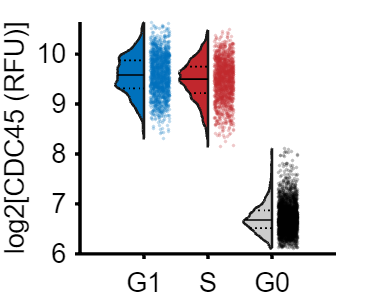

ans = 1715

ans = 1432

ans = 3000

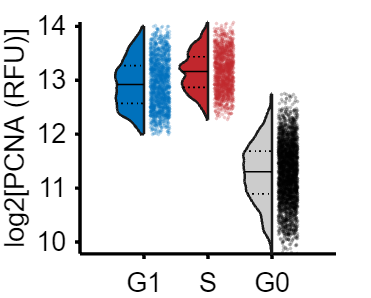

ans = 1693

ans = 1638

ans = 3000

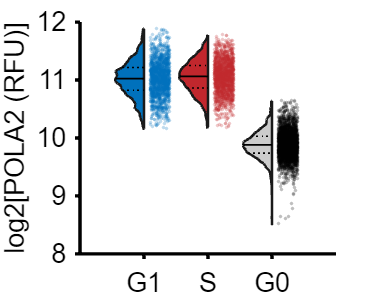

ans = 1722

ans = 1602

ans = 3000

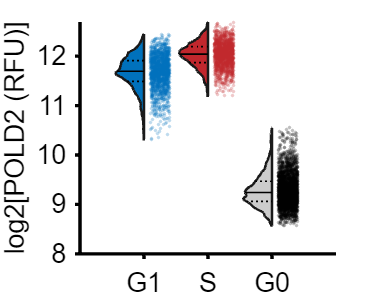

ans = 1800

ans = 1517

ans = 3000

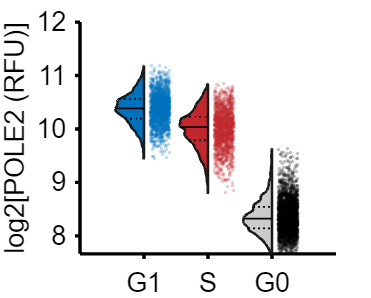

ans = 1812

ans = 1606

ans = 3000

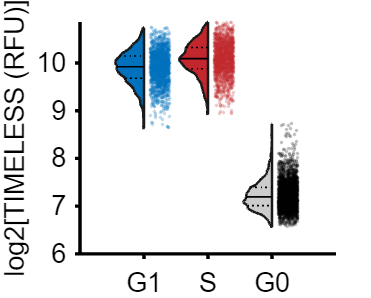

drugs = {'DMSO','DMSO','starve'};
phase = {'G1','S','G0'};
names = {'G1','S','G0'};
colors = [0 113 188; 193 39 45; 77,175,74]/255;
colorval = [1 2 3];
stains = {'CDC45','PCNA','POLA2','POLD2','POLE2','TIMELESS'};

for j = 1:length(stains)
    ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),3);

    stain = stains{j};
 
    for i=1:length(names)
        data = dfGated(dfGated.antibody == stain,:);
        data = data(data.drugTreatment == drugs{i} & data.phase == phase{i} & data.extractTreatment == 'total',:);

        xdata = log2(data.stain);
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
        if strcmp(names{i}, 'G0')
            xdata = randsample(xdata,3000,false);
        end
        
        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(names{i}, 'G1')
            outmat(j,1) = median(xdata);
        elseif strcmp(names{i},'S')
            outmat(j,2) = median(xdata);
        elseif strcmp(names{i},'G0')
            outmat(j,3) = median(xdata);
        end
        length(xdata)
    end
    


cols = repmat({colors(1,:),colors(2,:),[.8 .8 .8]}',1,1);
groupcol = repmat([ colors([1 2 ],:);0 0 0],1,1);

figure('Units', 'Inches', 'Position', [0, 0, 5, 4])

h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'log2[' stain ' (RFU)]'])

xticklabels({'G1','S','G0'})

 % print_pdf([pwd() stain '.pdf'])

end

**comparing stain expression in G1 cells (3-4 h after mitosis), S phase cells (1-2 h after S entry) and starved cells**

ans = 3000

ans = 1959

ans = 1703

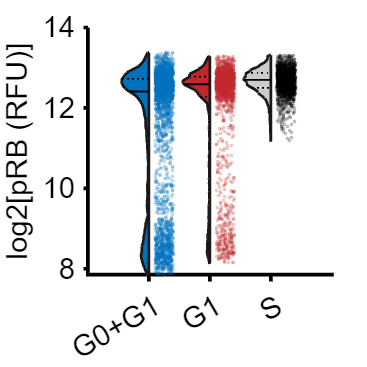


drugs = {'cycling','DMSO','DMSO'};
phase = {'all','G1','S'};
names = {'all','G1','S'};
colors = [0 113 188; 193 39 45; 77,175,74]/255;
colorval = [1 2 3];
stains = {'pRB'};

for j = 1:length(stains)
    ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),3);

    stain = stains{j};

    for i=1:length(names)
        data = dfGated(dfGated.antibody == stain,:);
        data = data(data.drugTreatment == drugs{i} & data.phase == phase{i} & data.extractTreatment == 'total',:);   
        xdata = log2(data.stain);
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
        if strcmp(names{i}, 'all')
            xdata = randsample(xdata,3000,false);
        end
        
        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(names{i}, 'G1')
            outmat(j,1) = median(xdata);
        elseif strcmp(names{i},'S')
            outmat(j,2) = median(xdata);
        elseif strcmp(names{i},'G0')
            outmat(j,3) = median(xdata);
        end
        length(xdata)
    end
    


cols = repmat({colors(1,:),colors(2,:),[.8 .8 .8]}',1,1);
groupcol = repmat([ colors([1 2 ],:);0 0 0],1,1);
figure('Units', 'Inches', 'Position', [0, 0, 5, 5])

h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'log2[' stain ' (RFU)]'])

xticklabels({'G0+G1','G1','S'})

% print_pdf([pwd() stain '_all.pdf'])
end